abbiamo le seguenti quote liquide di FRA pagati posticipatamente. Assumiamo che gli intervalli sono di 30gg

FRA3x6bid=0.045;
FRA3x6ask=0.046;
FRA6x9bid=0.047;
FRA6x9ask=0.048;
FRA9x12bid=0.05;
FRA9x12ask=0.051;
FRA12x15bid=0.055;
FRA12x15ask=0.057;
FRA15x18bid=0.061;
FRA15x18ask=0.063;
V=[FRA3x6bid FRA6x9bid FRA9x12bid FRA12x15bid FRA15x18bid];
L=zeros(1,length(V));
L(1,1)=0.04;


a)calcolare i pressi dei bon partendo dai 6 mesi fino a 18 mesi


num=100;
B=zeros(1,length(V));
for i=1:length(V)
    den=prod(1+0.25*V(1:i));
    B(1,i)=num/den;
end
disp(B)

   98.8875   97.7391   96.5324   95.2231   93.7928



b)calcolare la struttura per scadenza per tutte le scadenze

Rf=zeros(1,length(V));
for i=1:length(V)
    Rf(1,i)=(num-B(1,i))/B(1,i);
end
disp(Rf)

    0.0112    0.0231    0.0359    0.0502    0.0662



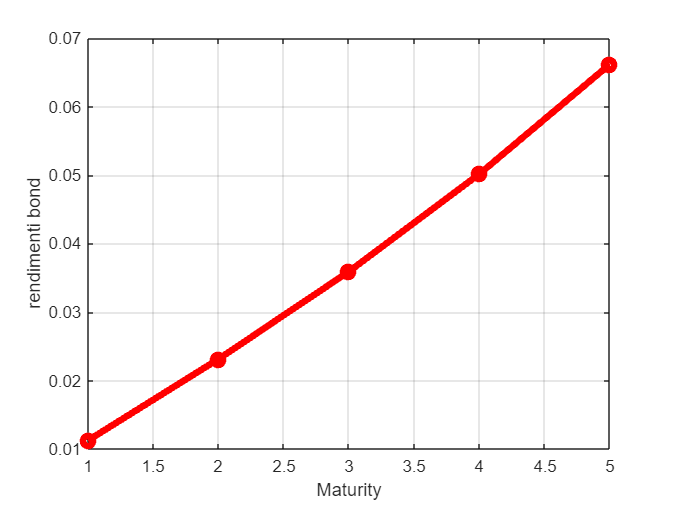

figure(1)
plot(Rf,LineWidth=4,Color='r',Marker='o')
xlabel('Maturity')
ylabel('rendimenti bond')
grid on;

%metto a grafico i rendimenti con i prezzi
figure;
scatter(Rf, B);
title('Relazione Prezzo-Rendimento');
xlabel('Rendimento');
ylabel('Prezzo');
grid on;

c)calcola la curva swap per le stesse scadenze

St0=zeros(1,4);
sum_B=sum(B(2:end));
Wi=zeros(1,4);
for i=1:4
    Nx=B(1,i+1);
    Wi(1,i)=Nx/sum_B;
St0=Wi(1,i)*V(1,i);
    

end
 %in questo caso ho calcolato il tasso swap di entrare in un contratto di
 %questo tipo a tutte le scadenze
disp(St0)

    0.0135



Calcolo il tasso swap per le singole scadenze

Stn=zeros(1,4);
for i=1:4
    Nxx=sum(B(1,2:1+i).*V(1,1:i));
    Dxx=sum(B(1,2:i+1));
    Stn(1,i)=Nxx/Dxx;
end
disp(Stn)

    0.0450    0.0460    0.0473    0.0492



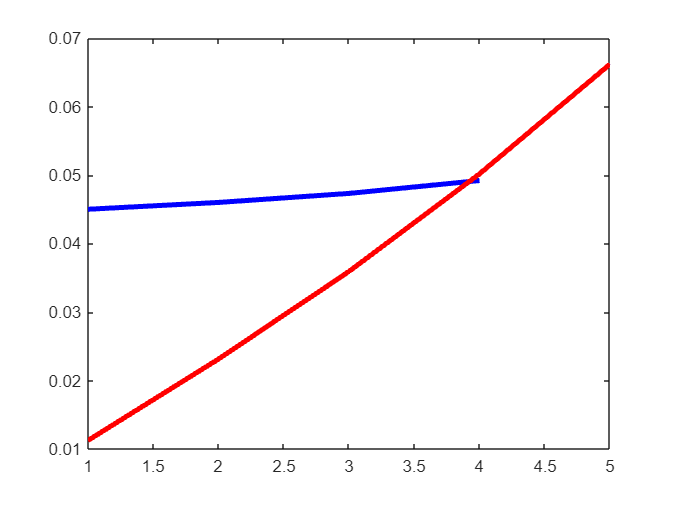


figure(2)
plot(Stn,LineWidth=3,Color='b')
hold on
plot(Rf,LineWidth=3,Color='r')